clear all
global omega0

KR_params();

$$ans = \left(\begin{array}{ccc} 2.4167e+03 & 0 & 0\\ 0 & 2.2375e+03 & 0\\ 0 & 0 & 2.1792e+03 \end{array}\right)$$

omega0 = deg2rad([-2 2 3]')*0;
omegaMax = deg2rad(1)

omegaMax = 0.0175


 % Масштаб спутника
ss = 0.5;

% Радиус планеты
Re=2;

% Высота над поверхностью планеты
H=2;

% Положение центра планеты
Ce=[0 0 0];

% Положение спутника
Co = [-1 1 1];
Co = Co/norm(Co);
Co = Ce + Co* (Re+H)

Co =    -2.3094    2.3094    2.3094



% Начальный и желаемый квантернионы
r_focus = [-0.289 1.514 1.275]

r_focus =    -0.2890    1.5140    1.2750


r_dst = r_focus - Co

r_dst =     2.0204   -0.7954   -1.0344


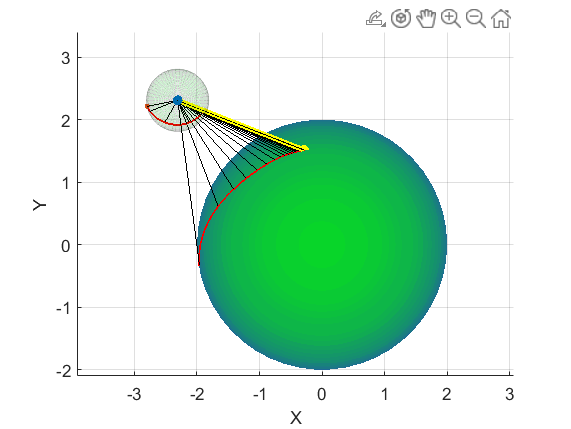

q0=transpose(axang2quat(vrrotvec([-1 -0.2 -0.1],[1 0 0])));
q_dst=transpose(axang2quat(vrrotvec(r_dst,[1 0 0])));

% Начальное направление
r=quatrotate(q0',[1 0 0]);
r=r/norm(r);

% Список векторов, задающих направление
R=[r];

% Интегрирование
tSim=500;
t=[0];
dt=0.1;
q=[q0];
w=[omega0];
u=[0;0;0];
while t(end) < tSim
    t(end+1) = t(end)+dt;
    w(:,end) = trimVector(w(:,end) ,deg2rad(20));
    [q1,w1,u1]= rotationTick(q(:,end),q_dst,w(:,end),2,0.1,J,dt);
    q=[q q1];
    w=[w w1];
    u=[u u1];
end
w=rad2deg(w);

for i=1:size(q,2)
    R=[R; quatrotate(q(:,i)',[1 0 0])];
end
R=R*ss;
X=R(:,1)+Co(1);
Y=R(:,2)+Co(2);
Z=R(:,3)+Co(3);

figure
%plot3(X,Y,Z,"LineWidth",2)
hold on
scatter3(Co(1),Co(2),Co(3),"filled");
scatter3(X(1),Y(2),Z(3),10,"filled");
%text(Co(1),Co(2),Co(3),"Спутник")


grid on
xlabel("X")
ylabel("Y")
zlabel("Z")
axis equal

% Отрисовка планеты
[Xs,Ys,Zs]=sphere(50);
Xe=Xs*Re;
Ye=Ys*Re;
Ze=Zs*Re;
s=surf(Xe+Ce(1),Ye+Ce(2),Ze+Ce(3));

colorsCount=50;
cm=[
    linspace(0.2,0,colorsCount)
    linspace(0,1,colorsCount)
    linspace(1,0,colorsCount)
    ]';
colormap(cm);
s.EdgeColor = 'none';

% Отрисовка спутника
s=surf(Xs*ss+Co(1),Ys*ss+Co(2),Zs*ss+Co(3));
alpha=0.1;
s.FaceAlpha = alpha;
s.EdgeAlpha = alpha/2;

% Проекция траектории на спутник
p=traceToSphere(Co,[X,Y,Z]-Co,Co,ss,false);
if ~isempty(p)
    xs=p(:,1);
    ys=p(:,2);
    zs=p(:,3);

    plot3(xs,ys,zs,"red","LineWidth",1)
    
    l=size(p,1);
    n=20;
    s=floor(l/n);

    for i=1:200:l
         plot3([Co(1) xs(i)],[Co(2) ys(i)],[Co(3) zs(i)],"k");
    end

end

% Проекция траектории на планету
p=traceToSphere(Co,[X,Y,Z]-Co,Ce,Re,true);
if ~isempty(p)
    xs=p(:,1);
    ys=p(:,2);
    zs=p(:,3);

    plot3(xs,ys,zs,"red","LineWidth",1)
    
    l=size(p,1);
    n=20;
    s=floor(l/n);

    for i=1:50:l
         plot3([Co(1) xs(i)],[Co(2) ys(i)],[Co(3) zs(i)],"k");
    end

end

% Проекция цели на сферу

p=traceToSphere(Co,r_dst,Ce,Re,true);
r_dst = r_dst+Co;

% Отрисовка цели
plot3(...
    [Co(1) r_dst(1)],...
    [Co(2) r_dst(2)],...
    [Co(3) r_dst(3)],"y","LineWidth",3);

if ~isempty(p)
    scatter3(p(1),p(2),p(3),"y","filled");
end

xlim([-3.91 3.06])
ylim([-2.10 3.40])

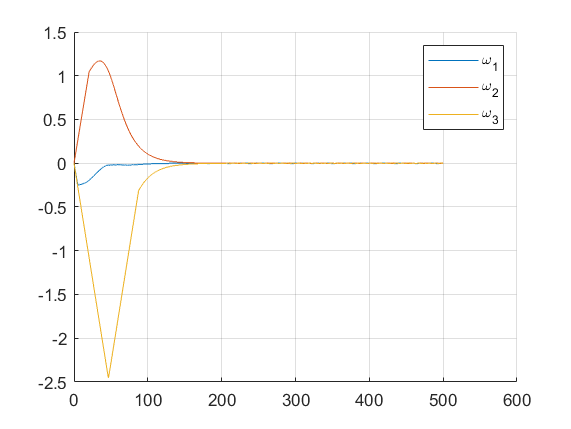


figure
hold on
plot(t,w(1,:))
plot(t,w(2,:))
plot(t,w(3,:))
grid on
legend("\omega_1","\omega_2","\omega_3")

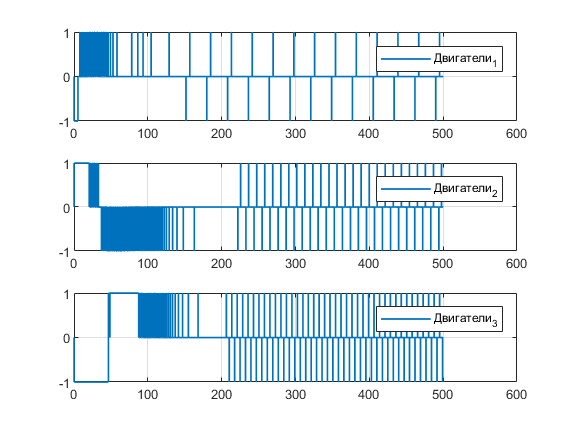


figure
tiledlayout(3,1)
lw=1;

ax1 = nexttile;
stairs(t,u(1,:),'LineWidth',lw)
grid on
legend("Двигатели_1")

ax2 = nexttile;
stairs(t,u(2,:),'LineWidth',lw)
grid on
legend("Двигатели_2")

ax3 = nexttile;
stairs(t,u(3,:),'LineWidth',lw)
grid on
legend("Двигатели_3")

linkaxes([ax1 ax2 ax3],'xy')